"Synthetic Data Generator" by Kambadur Ananthamurthy

This code uses real dF/F data, populates a library of calcium events, and then creates a synthetic dataset based on the control parameters.

Here is a list of functions or other scripts called within this main script:

- setupSyntheticDataParameters.m

- findConsecutiveOnes.m

- syntheticDataMaker.m

- generateNoise.m

- plotdFbyF.m

- getPSTH.m

Please ensure that you have acess to all of them before proceeding.

tic
close all
clear

addpath(genpath('/Users/ananth/Documents/MATLAB/CustomFunctions')) % my custom functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis')) % Additional functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis/Suite2P-ananth'))


## Operations

This section provides some operational controls.

%ops0.fig             = 1;
ops0.saveData        = 0;

figureDetails = compileFigureDetails(16, 2, 10, 0.5, 'jet'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
%ops0.onlyProbeTrials = 0

## Real Dataset Details

Here, one must provide details of the real dataset to be referenced while making the synthetic data. The code uses some of these parameters to locate the file containing the real dF/F data, while the other parameters are important for functions and plotting. The structure of this section is directly as is required for the Suite-2P analysis pipeline.

It is crucial to use dF/F values rather than the raw fluorescence traces, since only then can the different calcium events be comparable.

make_db
% db.mouseName    = 'M26';
% db.date          = '20180514';
% db.sessionType   = 5;
% db.session       = 4;
% db.nFrames       = 246;
% db.samplingRate  = 14.47; %Hz
% db.nTrials       = 60; %usable trials
% db.comments      = 'TEC: 500 ms ISI';
% db.trialDuration = 17; %in seconds
% db.expts         = 1;
% db.nplanes       = 1;

fprintf('Reference Dataset - %s_%i_%i | Date: %s\n', db.mouseName, ...
    db.sessionType, ...
    db.session, ...
    db.date)

Reference Dataset - M26_5_4 | Date: 20180514


## Load dF/F

We then load the real processed data based on the reference dataset.

saveDirec = '/Users/ananth/Desktop/Work/Analysis/Imaging/';
saveFolder = [saveDirec db.mouseName '/' db.date '/'];

%Load processed data (processed dfbf for dataset/session)
realProcessedData = load([saveFolder db.mouseName '_' db.date '.mat']);
nCells = size(realProcessedData.dfbf, 1);
nTrials = size(realProcessedData.dfbf, 2);
nFrames = size(realProcessedData.dfbf, 3);
fprintf('Total cells: %i\n', nCells)

Total cells: 135


## Synthetic Data Control Parameters

Here, one must provide all the control parameters required to generate the synthetic data. These can be found in a header-like file called setupSyntheticDataParameters.m. This sort of implementation ensures minimal (if any) change to this main script, while changing parameters.

setupSyntheticDataParameters

## Curate Calcium Event Library

This next section of code ensures that we have a working library of calcium events.

%Cell specific curation of the calcium event library
%Check to see if the library exits
if isfile([saveFolder db.mouseName '_' db.date '_eventLibrary_2D.mat'])
    disp('Loading existing event library ...')
    load([saveFolder db.mouseName '_' db.date '_eventLibrary_2D.mat'])
    disp('... done!')
else
    %Use real 2D data
    cellMean = zeros(nCells, 1);
    cellStddev = zeros(nCells, 1);
    binaryData = zeros(nCells, 1);
    
    %2D
    disp('Basic scan for calcium events ...')
    for cell = 1:nCells
        sampledTrial = squeeze(realProcessedData.dfbf_2D(cell, :));
        cellMean(cell) = mean(sampledTrial);
        cellStddev(cell) = std(sampledTrial);
        binaryData(find(sampledTrial > (cellMean(cell) + 2*cellStddev(cell))), 1) = 1; %multiplier = 1
        [nEvents, StartIndices, Lengths] = findConsecutiveOnes(binaryData);
        eventLibrary_2D(cell).nEvents = nEvents;
        eventLibrary_2D(cell).eventStartIndices = StartIndices;
        eventLibrary_2D(cell).eventLengths = Lengths;
        
        clear binaryData
        clear Events
        clear StartIndices
        clear Lengths
    end
    disp('... library curated!')
end

Basic scan for calcium events ...


... library curated!


## Make Synthetic Data

This is business end. We call the syntheticDataMaker function with the control parameters passed in as arguments.

[syntheticDATA, syntheticDATA_2D, ...
    ptcList, ocList, ...
    actualEventWidth, ...
    hitTrialPercent, hitTrials, ...
    frameIndex, pad, ...
    noiseComponent] = syntheticDataMaker(db, realProcessedData.dfbf_2D, eventLibrary_2D, ...
    timeCellPercent, cellOrder, ...
    maxHitTrialPercent, hitTrialPercentAssignment, trialOrder, ...
    eventWidth, eventAmplificationFactor, eventTiming, startFrame, endFrame, ...
    imprecisionFWHM, imprecisionType, ...
    noise, noisePercent);

Creating synthetic data ...
... Number of Putative Time Cells: 67
... done!


## Quality Metric

Next, we develop a quality metric "Q', to assign a reliability score to every cell in the synthetic dataset.


$$Q=\frac{\mathrm{Hit}\text{ }\mathrm{Trial}\text{ }\mathrm{Percent}\ast \mathrm{Event}\text{ }\mathrm{Amplification}\text{ }\mathrm{Factor}}{\left(\mathrm{Actual}\text{ }\mathrm{Event}\text{ }\mathrm{Width}\text{ }\mathrm{Max}\text{ }-\text{ }\mathrm{Actual}\text{ }\mathrm{Event}\text{ }W\mathrm{idth}\text{ }\mathrm{Min}+\text{ }\mathrm{Imprecision}\right)\ast \mathrm{Noise}\text{ }\mathrm{Percent}}$$


Here, the Hit Trial Percent and the Actual Event Widths are cell specific, while the other controls are fixed for every cell (specified as synthetic data control parameters).

Q = zeros(nCells, 1);
for cell = 1:nCells
    Q(cell) = (hitTrialPercent(cell) * eventAmplificationFactor)/((actualEventWidth(cell, 2) - actualEventWidth(cell, 1) + imprecisionFWHM) * noisePercent);
end

## Plots

We can now visualize the synthetic dataset along with checks to ensure the control parameters are working as expected

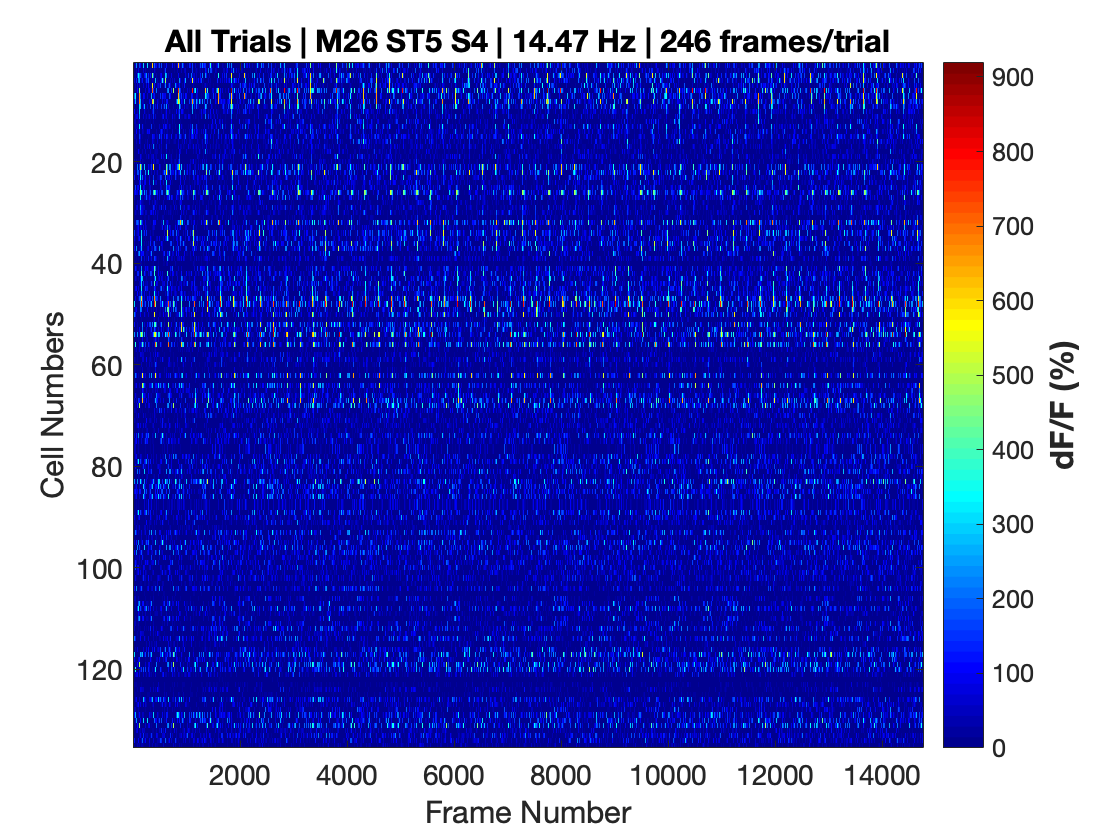

% All trials
figure(1)
clf
plotdFbyF(db, syntheticDATA_2D, 'All Trials', 'Frame Number', 'Cell Numbers', figureDetails, 0)
colormap(figureDetails.colorMap)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

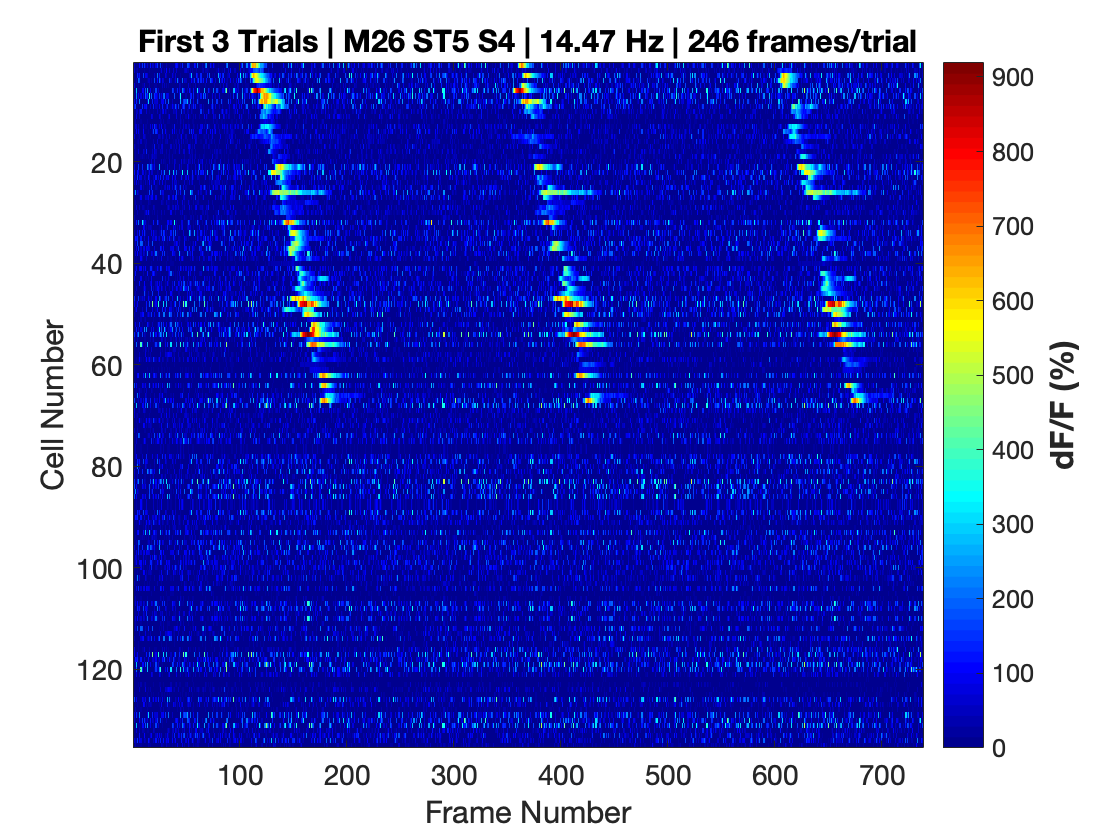


% Only first 3 trials
figure(2)
clf
plotdFbyF(db, syntheticDATA_2D(:,1:(3*db.nFrames)), 'First 3 Trials', 'Frame Number', 'Cell Number', figureDetails, 0)
colormap(figureDetails.colorMap)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_first3trials_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

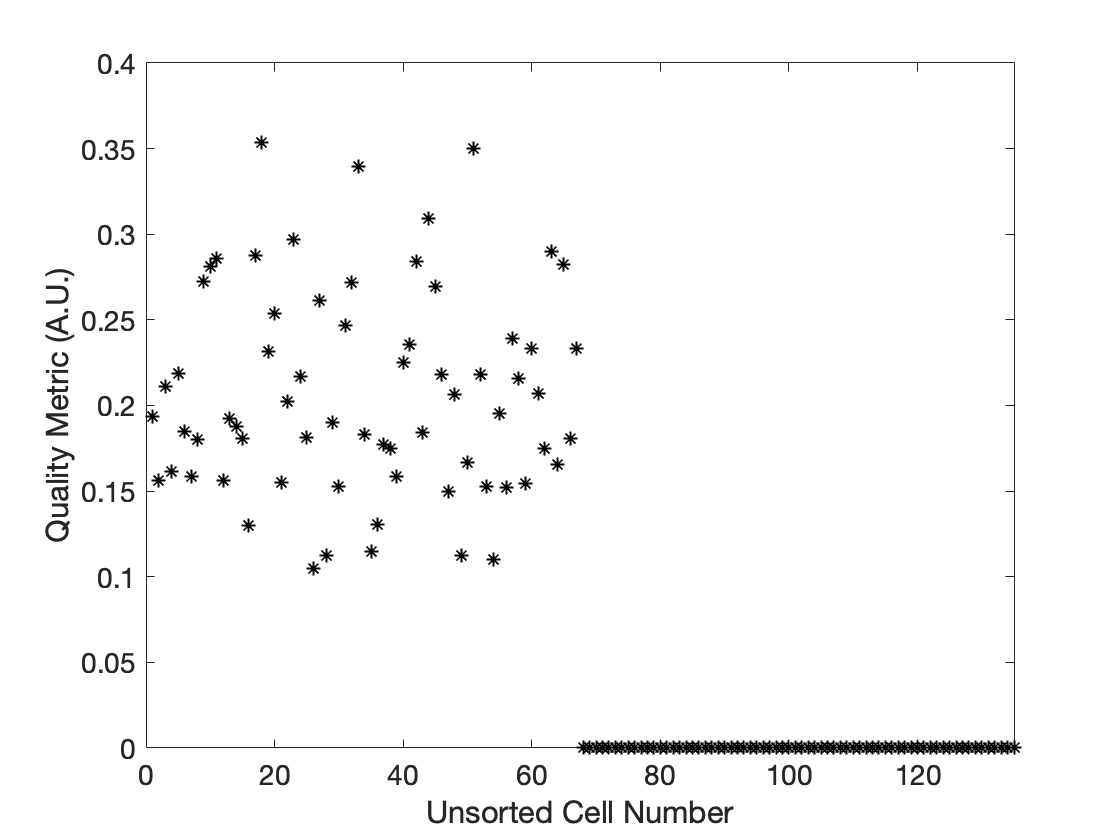

% Quality metric (Q)
figure(3)
clf
plot(Q, 'k*')
xlim([0 nCells])
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Quality Metric (A.U.)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_Q_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

% Event Time Histograms
delta = 3;
skipFrames = [];
[PSTH, PSTH_3D, nbins] = getPSTH(syntheticDATA, delta, skipFrames);

Now, developing PSTH for 135 cells ...
... 10 cells analysed ...
... 20 cells analysed ...
... 30 cells analysed ...
... 40 cells analysed ...
... 50 cells analysed ...
... 60 cells analysed ...
... 70 cells analysed ...
... 80 cells analysed ...
... 90 cells analysed ...
... 100 cells analysed ...
... 110 cells analysed ...
... 120 cells analysed ...
... 130 cells analysed ...
... done!


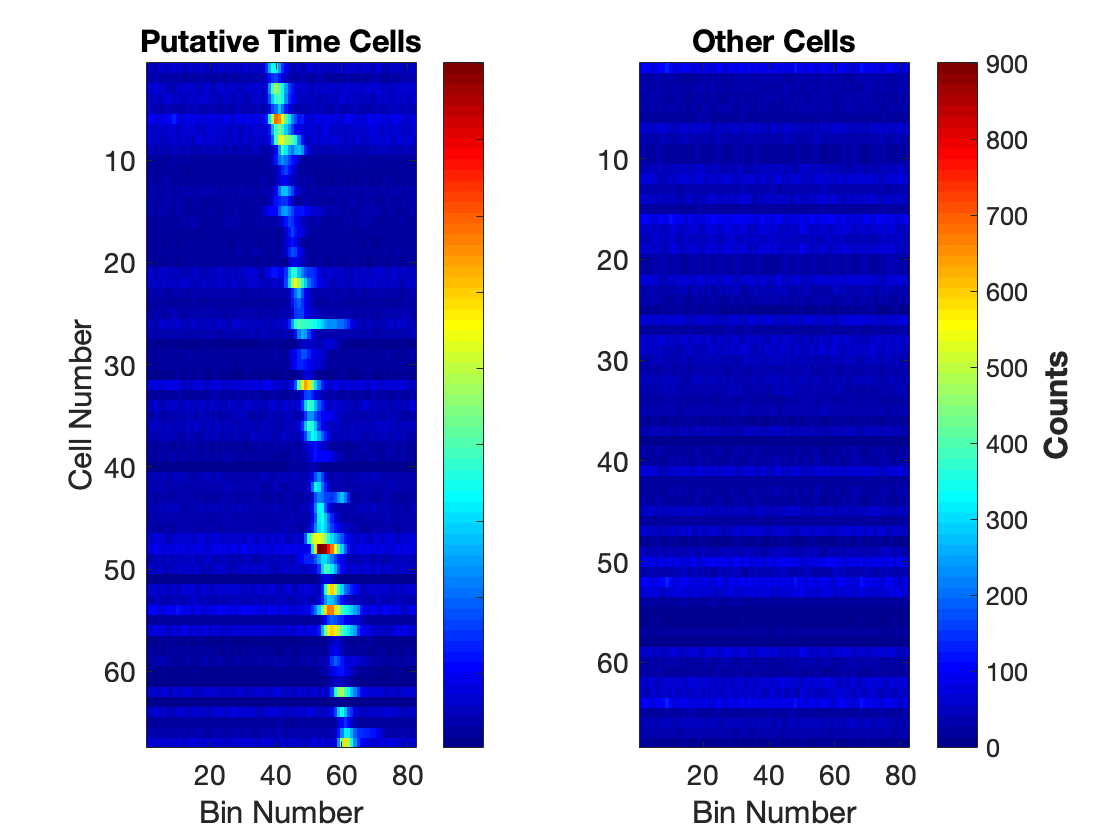

figure(4)
clf
subplot(1,2,1)
imagesc(PSTH(ptcList,:)); % Putative Time Cells
z = colorbar;
set(z,'YTickLabel',({}))
colormap('jet')
%caxis([0 max(max(PSTH(ptcList,:)))])
title('Putative Time Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Bin Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(1,2,2)
imagesc(PSTH(ocList,:)); % Other Cells
z = colorbar;
caxis([0 max(max(PSTH(ptcList,:)))]) % NOTE: setting limits based on the same expected for putative time cells.
ylabel(z,'Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
colormap('jet')
title('Other Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Bin Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% ylabel('Cell Number', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_PSTH_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

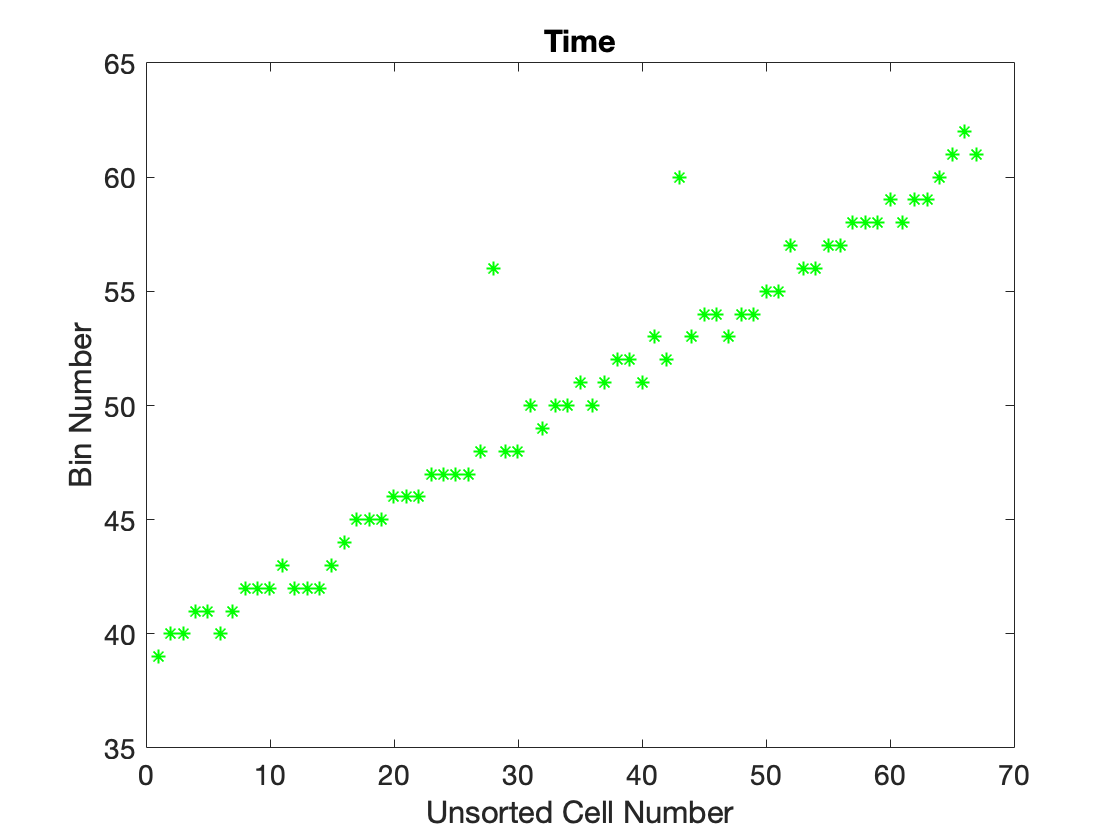

% What time is it?
[~, T] = max(PSTH(ptcList,:), [], 2); % Time Vector
figure(5)
clf
plot(T, 'g*')
title('Time', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Bin Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_T_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

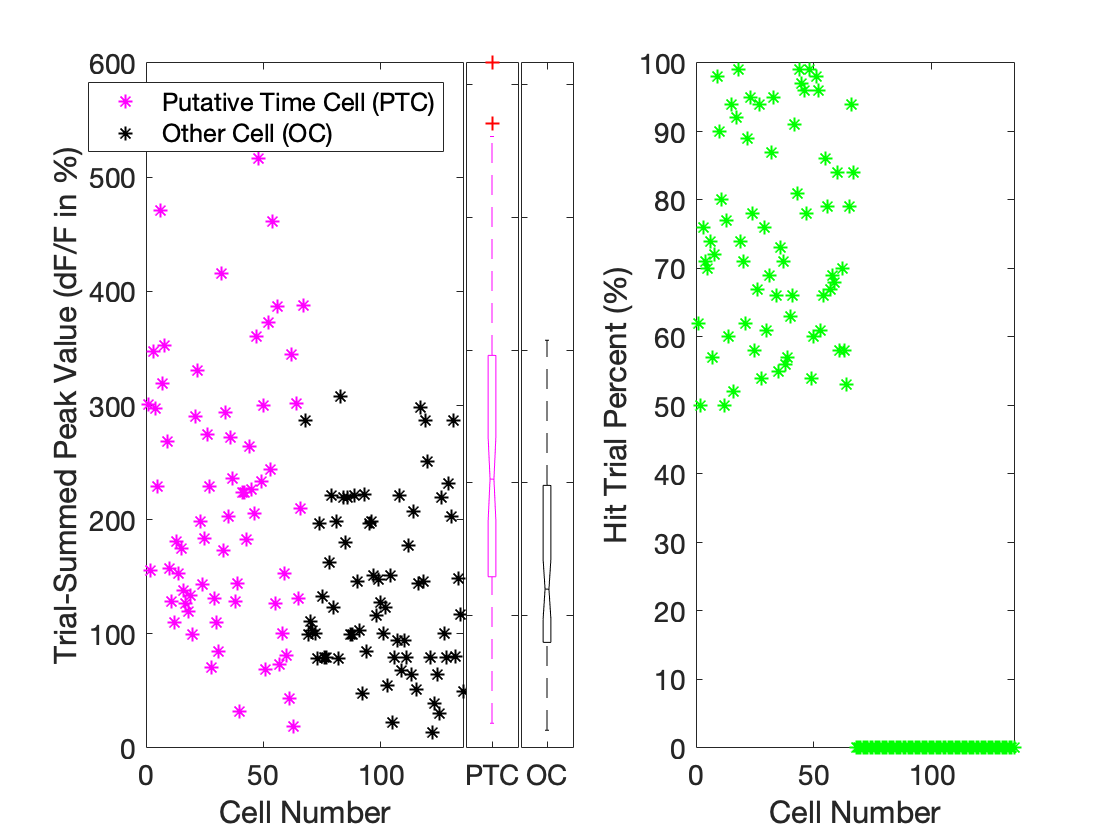

% Check - Percent Time Cells, Percent Hit Trials, Event Amplification Factor
sdtc_peaks = nan(nCells, nTrials); % Putative Time Cells
sdoc_peaks = nan(nCells, nTrials); % Other Cells
for cell = 1:nCells
        for trial = 1:nTrials
            if ismember(cell, ptcList)
                sdtc_peaks(cell, trial) = max(syntheticDATA(cell, trial, :));
            else
                sdoc_peaks(cell, trial) = max(syntheticDATA(cell, trial, :));
            end
        end
end
X1 = sum(sdtc_peaks, 2);
X2 = sum(sdoc_peaks, 2);

figure(6)
clf
subplot(1,16,1:6)
plot(X1, 'm*')
hold on
plot(X2, 'k*')
hold off
if length(X1) > length(X2)
    xlim([0 length(X1)])
else
    xlim([0 length(X2)])
end
% title('Putative Time Cells vs Other Cells', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
xlabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Trial-Summed Peak Value (dF/F in %)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
legend('Putative Time Cell (PTC)', 'Other Cell (OC)')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(1,16,7)
boxplot(X1, ...
    'Notch','on', ...
    'Labels',{'PTC'}, ...
    'Whisker', 1, ...
    'Color', 'm')
ylim([0 max(X1)])
set(gca,'YTick',0:100:max(X1))
set(gca,'YTickLabel',[])
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(1,16,8)
boxplot(X2, ...
    'Notch','on', ...
    'Labels',{'OC'}, ...
    'Whisker', 1, ...
    'Color', 'k')
ylim([0 max(X1)])
set(gca,'YTick',0:100:max(X1))
set(gca,'YTickLabel',[])
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(1,16,11:16)
plot(hitTrialPercent, 'g*')
xlim([0 nCells])
ylim([0 100])
xlabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Hit Trial Percent (%)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_trialSummedPeaks_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

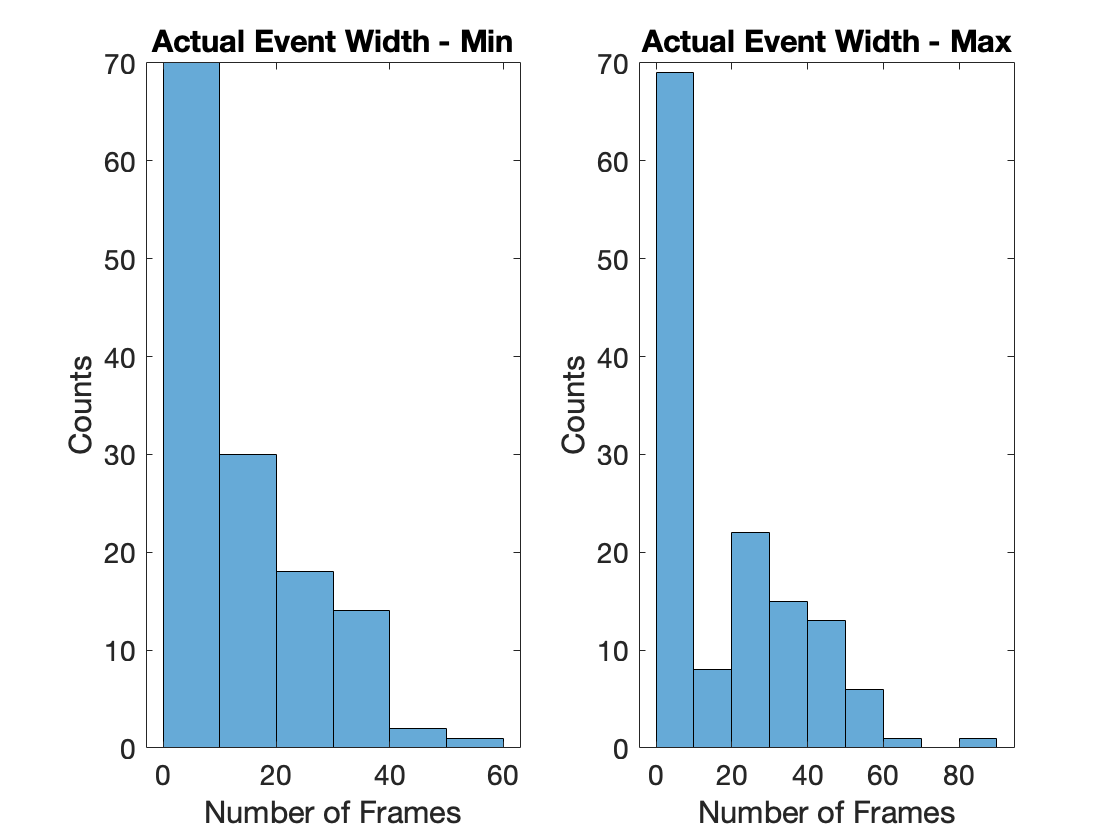

% Check - Event Lengths (Exclusively for Putative Time Cells)
figure(7)
clf
subplot(1,2,1)
histogram(actualEventWidth(:,1)); % Min
title('Actual Event Width - Min', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(1,2,2)
histogram(actualEventWidth(:,2)); % Max

title('Actual Event Width - Max', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_actualEventWidth_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

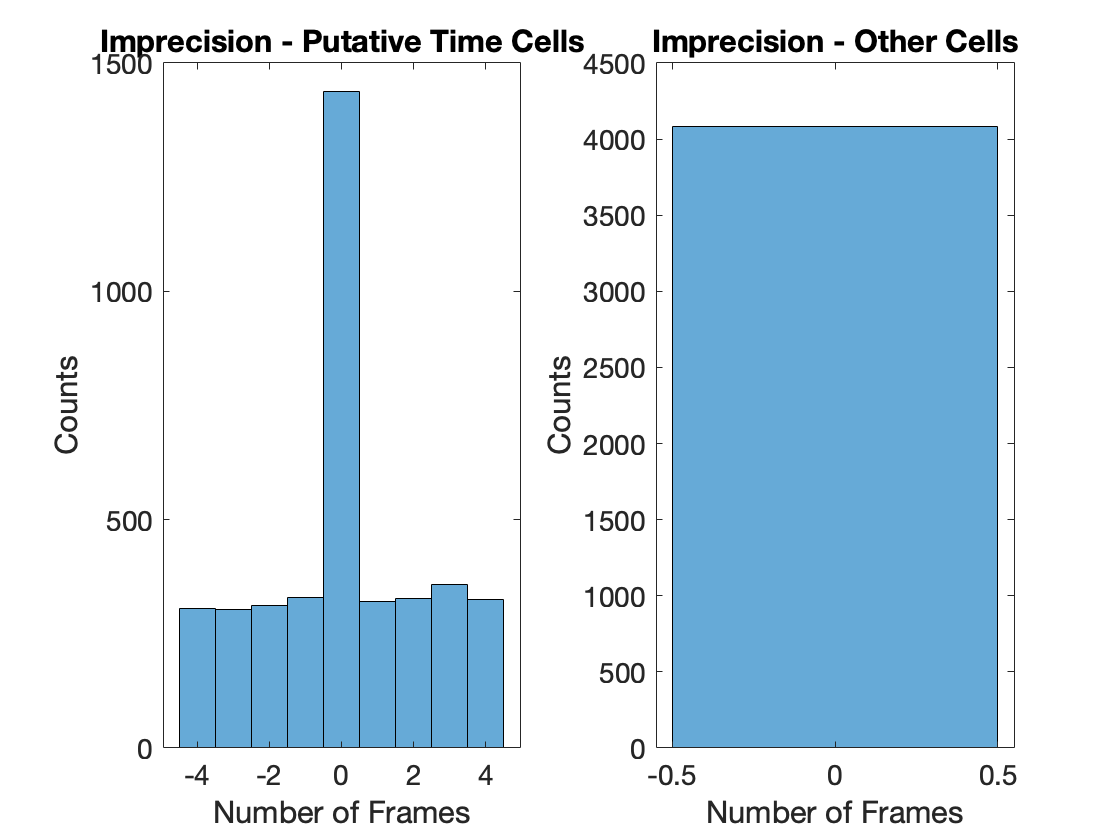


% Check - ImprecisionFWHM
pad_tc = pad(ptcList,:); % Putative Time Cells
pad_oc = pad(ocList,:); % Other Cells

figure(8)
clf
subplot(1,2,1)
histogram(pad_tc)
title('Imprecision - Putative Time Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(1,2,2)
histogram(pad_oc)
title('Imprecision - Other Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_imprecision_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

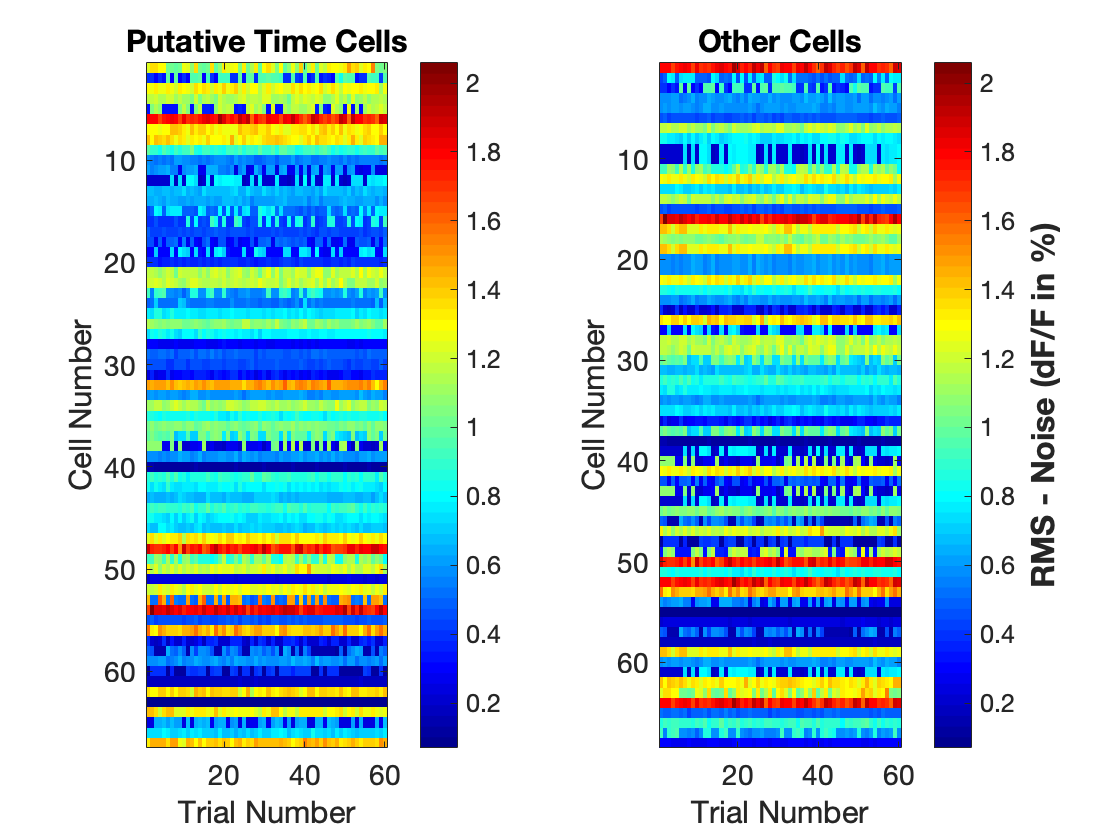

% Check - Noise
nctc = noiseComponent(ptcList, :, :); % Putative Time Cells
ncoc = noiseComponent(ocList, :, :); % Other Cells

rms_tc = zeros(length(ptcList), nTrials); % Putative Time Cells
rms_oc = zeros(length(ocList), nTrials); % Other Cells

for cell = 1:size(nctc, 1)
    for trial = 1:size(nctc, 2)
        rms_tc(cell, trial) = rms(nctc(cell, trial, :), 3);
    end
end

for cell = 1:size(ncoc, 1)
    for trial = 1:size(ncoc, 2)
        rms_oc(cell, trial) = rms(ncoc(cell, trial, :), 3);
    end
end

figure(9);
clf
subplot(1,7,1:3)
imagesc(rms_tc)
colorbar
colormap(figureDetails.colorMap)
z = colorbar;
% ylabel(z,'RMS - dF/F (%)', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
title('Putative Time Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Trial Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(1,7,5:7)
imagesc(rms_oc)
colorbar
colormap(figureDetails.colorMap)
z = colorbar;
ylabel(z,'RMS - Noise (dF/F in %)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
title('Other Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Trial Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_noiseComponent_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

## Save data

Finally, it is crucial to save not just the dataset but also all the control parameters involved, in one convenient location.

if ops0.saveData == 1
    save([saveFolder db.mouseName '_' db.date '_eventLibrary_2D.mat'], 'eventLibrary_2D')
    save([saveFolder ...
        'synthDATA' ...
        '_pTC' num2str(timeCellPercent) ...
        '_cO' lower(cellOrder) ...
        '_mPHT' num2str(maxHitTrialPercent) ...
        '_hTA' lower(hitTrialPercentAssignment) ...
        '_tO' lower(trialOrder) ...
        '_eW' num2str(eventWidth{1}) '-' eventWidth{2} ...
        '_eAF' eventAmplificationFactor ...
        '_eT' lower(eventTiming) ...
        '_sF' num2str(startFrame) ...
        '_eF' num2str(endFrame) ...
        '_iFWHM' num2str(imprecisionFWHM) ...
        '_iT' lower(imprecisionType) ...
        '_n' lower(noise) ...
        '_np' num2str(noisePercent) ...
        '.mat'], ...
        'syntheticDATA', 'syntheticDATA_2D', 'Q', 'T', ...
        'ptcList', 'ocList', ...
        'actualEventWidth', ...
        'hitTrialPercent', 'hitTrials', ...
        'frameIndex', 'pad', ...
        'noiseComponent', ...
        'timeCellPercent', 'cellOrder', ...
        'maxHitTrialPercent', 'hitTrialPercentAssignment', 'trialOrder', ...
        'eventWidth', 'eventTiming', ...
        'startFrame', 'endFrame', ...
        'imprecisionFWHM', 'imprecisionType', ...
        'noise', 'noisePercent')
end
toc

Elapsed time is 37.237268 seconds.


disp('All done!')

All done!
